%% GPR 기반 연속 설계 공간 최적 설계 탐색 - 다양한 가중치 조합

% Step 0: 사전 준비
load('Vib_Data.mat');
params_tbl = readtable('LHS 파라미터(csv).csv');


% 출력 변수들
roll_angle_rms = T_all.RollAngle_RMS_deg;
lat_acc_rms     = T_all.RMS_LateralAcc_ms2;
heave_rms       = T_all.RMS_HeaveAcc_ms2;
pitch_acc_rms   = T_all.Pitch_Acc_RMS_degps2;
roll_acc_rms    = T_all.Roll_Acc_RMS_degps2;
psd_rms         = T_all.Heave_PSD_RMS_mps2;

% 정규화 및 점수화
normalize = @(x) (x - min(x)) / (max(x) - min(x));
roll_norm   = normalize(roll_angle_rms);
lat_norm    = normalize(lat_acc_rms);
pitch_norm  = normalize(pitch_acc_rms);
rolla_norm  = normalize(roll_acc_rms);
heave_norm  = normalize(heave_rms);
psd_norm    = normalize(psd_rms);

Handling_Score = 0.5 * (1 - roll_norm) + 0.5 * (1 - lat_norm);
Comfort_Score  = 0.3 * (1 - heave_norm) + 0.3 * (1 - psd_norm) + ...
                 0.2 * (1 - pitch_norm) + 0.2 * (1 - rolla_norm);

% GPR 학습용 입력
X_train = [params_tbl.Spring, params_tbl.Comp_F, params_tbl.Reb_F, ...
           params_tbl.Comp_R, params_tbl.Reb_R];

% GPR 모델 학습
gprModel_handling = fitrgp(X_train, Handling_Score, ...
    'KernelFunction','ardsquaredexponential','Standardize',true);
gprModel_comfort = fitrgp(X_train, Comfort_Score, ...
    'KernelFunction','ardsquaredexponential','Standardize',true);

% Step 1: LHS 설계 공간 생성
n_samples = 100000;
lhs = lhsdesign(n_samples, 5, 'criterion', 'maximin', 'iterations', 100);

spring_samples = lhs(:,1) * (4 - 1) + 1;
compF_samples  = lhs(:,2) * (12 - 1) + 1;
rebF_samples   = lhs(:,3) * (22 - 1) + 1;
compR_samples  = lhs(:,4) * (12 - 1) + 1;
rebR_samples   = lhs(:,5) * (22 - 1) + 1;
X_query_full = [spring_samples, compF_samples, rebF_samples, compR_samples, rebR_samples];

% Step 2: 예측
H_pred = predict(gprModel_handling, X_query_full);
C_pred = predict(gprModel_comfort, X_query_full);

% Step 3: 다양한 가중치 비율 반복
w_list = linspace(1, 0, 11);  % [1.0, 0.9, ..., 0.0]

figure('Name','Total Score Distribution All Weights');
tiledlayout(3,4,'Padding','compact','TileSpacing','compact');

for i = 1:length(w_list)
    w_h = w_list(i);
    w_c = 1 - w_h;

    % Total Score 계산
    total_score = w_h * H_pred + w_c * C_pred;

    % 최적 설계 선택
    [~, best_idx] = max(total_score);
    best_design = X_query_full(best_idx, :);

    % 개별 결과 출력
    fprintf('\n== [w_h: %.1f, w_c: %.1f] 최적 설계 ==\n', w_h, w_c);
    fprintf('Spring Level     = %.2f\n', best_design(1));
    fprintf('Comp_F Level     = %.2f\n', best_design(2));
    fprintf('Reb_F Level      = %.2f\n', best_design(3));
    fprintf('Comp_R Level     = %.2f\n', best_design(4));
    fprintf('Reb_R Level      = %.2f\n', best_design(5));
    fprintf('Handling Score   = %.4f\n', H_pred(best_idx));
    fprintf('Comfort Score    = %.4f\n', C_pred(best_idx));
    fprintf('Total Score      = %.4f\n', total_score(best_idx));

    % 시각화 (subplot 형태)
    nexttile;
    scatter(H_pred, C_pred, 5, total_score, 'filled'); hold on;
    plot(H_pred(best_idx), C_pred(best_idx), 'r*', 'MarkerSize', 8, 'LineWidth', 1.5);
    xlabel('Handling'); ylabel('Comfort');
    title(sprintf('w_h=%.1f, w_c=%.1f', w_h, w_c));
    grid on;
end


== [w_h: 1.0, w_c: 0.0] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 4.87


Reb_F Level      = 3.76


Comp_R Level     = 7.17


Reb_R Level      = 9.00


Handling Score   = 1.0423


Comfort Score    = 0.8737


Total Score      = 1.0423



== [w_h: 0.9, w_c: 0.1] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 4.87


Reb_F Level      = 3.76


Comp_R Level     = 7.17


Reb_R Level      = 9.00


Handling Score   = 1.0423


Comfort Score    = 0.8737


Total Score      = 1.0254



== [w_h: 0.8, w_c: 0.2] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 4.87


Reb_F Level      = 3.76


Comp_R Level     = 7.17


Reb_R Level      = 9.00


Handling Score   = 1.0423


Comfort Score    = 0.8737


Total Score      = 1.0086



== [w_h: 0.7, w_c: 0.3] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 5.91


Reb_F Level      = 6.44


Comp_R Level     = 7.48


Reb_R Level      = 8.53


Handling Score   = 1.0206


Comfort Score    = 0.9333


Total Score      = 0.9944



== [w_h: 0.6, w_c: 0.4] 최적 설계 ==


Spring Level     = 3.98


Comp_F Level     = 10.23


Reb_F Level      = 5.78


Comp_R Level     = 6.88


Reb_R Level      = 10.00


Handling Score   = 0.9810


Comfort Score    = 0.9983


Total Score      = 0.9880



== [w_h: 0.5, w_c: 0.5] 최적 설계 ==


Spring Level     = 3.98


Comp_F Level     = 10.23


Reb_F Level      = 5.78


Comp_R Level     = 6.88


Reb_R Level      = 10.00


Handling Score   = 0.9810


Comfort Score    = 0.9983


Total Score      = 0.9897



== [w_h: 0.4, w_c: 0.6] 최적 설계 ==


Spring Level     = 3.98


Comp_F Level     = 10.23


Reb_F Level      = 5.78


Comp_R Level     = 6.88


Reb_R Level      = 10.00


Handling Score   = 0.9810


Comfort Score    = 0.9983


Total Score      = 0.9914



== [w_h: 0.3, w_c: 0.7] 최적 설계 ==


Spring Level     = 3.98


Comp_F Level     = 10.23


Reb_F Level      = 5.78


Comp_R Level     = 6.88


Reb_R Level      = 10.00


Handling Score   = 0.9810


Comfort Score    = 0.9983


Total Score      = 0.9931



== [w_h: 0.2, w_c: 0.8] 최적 설계 ==


Spring Level     = 3.98


Comp_F Level     = 10.23


Reb_F Level      = 5.78


Comp_R Level     = 6.88


Reb_R Level      = 10.00


Handling Score   = 0.9810


Comfort Score    = 0.9983


Total Score      = 0.9949



== [w_h: 0.1, w_c: 0.9] 최적 설계 ==


Spring Level     = 3.98


Comp_F Level     = 10.23


Reb_F Level      = 5.78


Comp_R Level     = 6.88


Reb_R Level      = 10.00


Handling Score   = 0.9810


Comfort Score    = 0.9983


Total Score      = 0.9966



== [w_h: 0.0, w_c: 1.0] 최적 설계 ==


Spring Level     = 3.98


Comp_F Level     = 10.23


Reb_F Level      = 5.78


Comp_R Level     = 6.88


Reb_R Level      = 10.00


Handling Score   = 0.9810


Comfort Score    = 0.9983


Total Score      = 0.9983


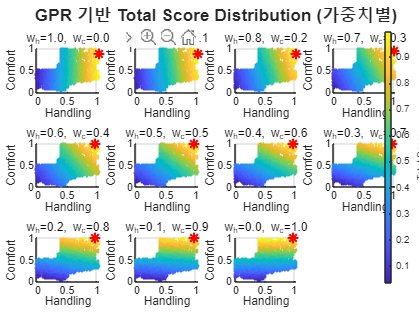


% 컬러바 (공통)
cb = colorbar('Position', [0.92 0.1 0.015 0.8]);
cb.Label.String = 'Total Score';
sgtitle('GPR 기반 Total Score Distribution (가중치별)', 'FontWeight','bold');